# PUMPKIN

clc; clear variables; close all;
bumps =10;
bdepth =0.1;
bdepth2 =0.02;
dimple =0.5;
width_r =1;
height_r =0.9;
[Xs, Ys, Zs] = sphere(199);
Rxy = (0-(1-mod(linspace(0,bumps*2,200),2)).^2)*bdepth + (0-(1-mod(linspace(0,bumps*4,200),2)).^2)*bdepth2;
Rz = (0-linspace(1,-1,200)'.^4)*dimple;
Xp = (width_r+Rxy).*Xs;
Yp = (width_r+Rxy).*Ys;
Zp = (height_r+Rz).*Zs.*(Rxy+1);
Cp = hypot(hypot(Xp,Yp),width_r.*Zs.*(Rxy+1));

## STEM

sheight =0.5;
scurve =0.3;
srad = [ 1.5 1 repelem(.7, 6) ] .* [ repmat([.1 .06],1,bumps) .1 ]';
[theta, phi] = meshgrid(linspace(0,pi/2,size(srad,2)),linspace(0,2*pi,size(srad,1)));
Xs = (scurve-cos(phi).*srad).*cos(theta)-scurve;
Zs = (sheight-cos(phi).*srad).*sin(theta) + height_r-max(0,dimple*.9);
Ys = -sin(phi).*srad;

## DRAW

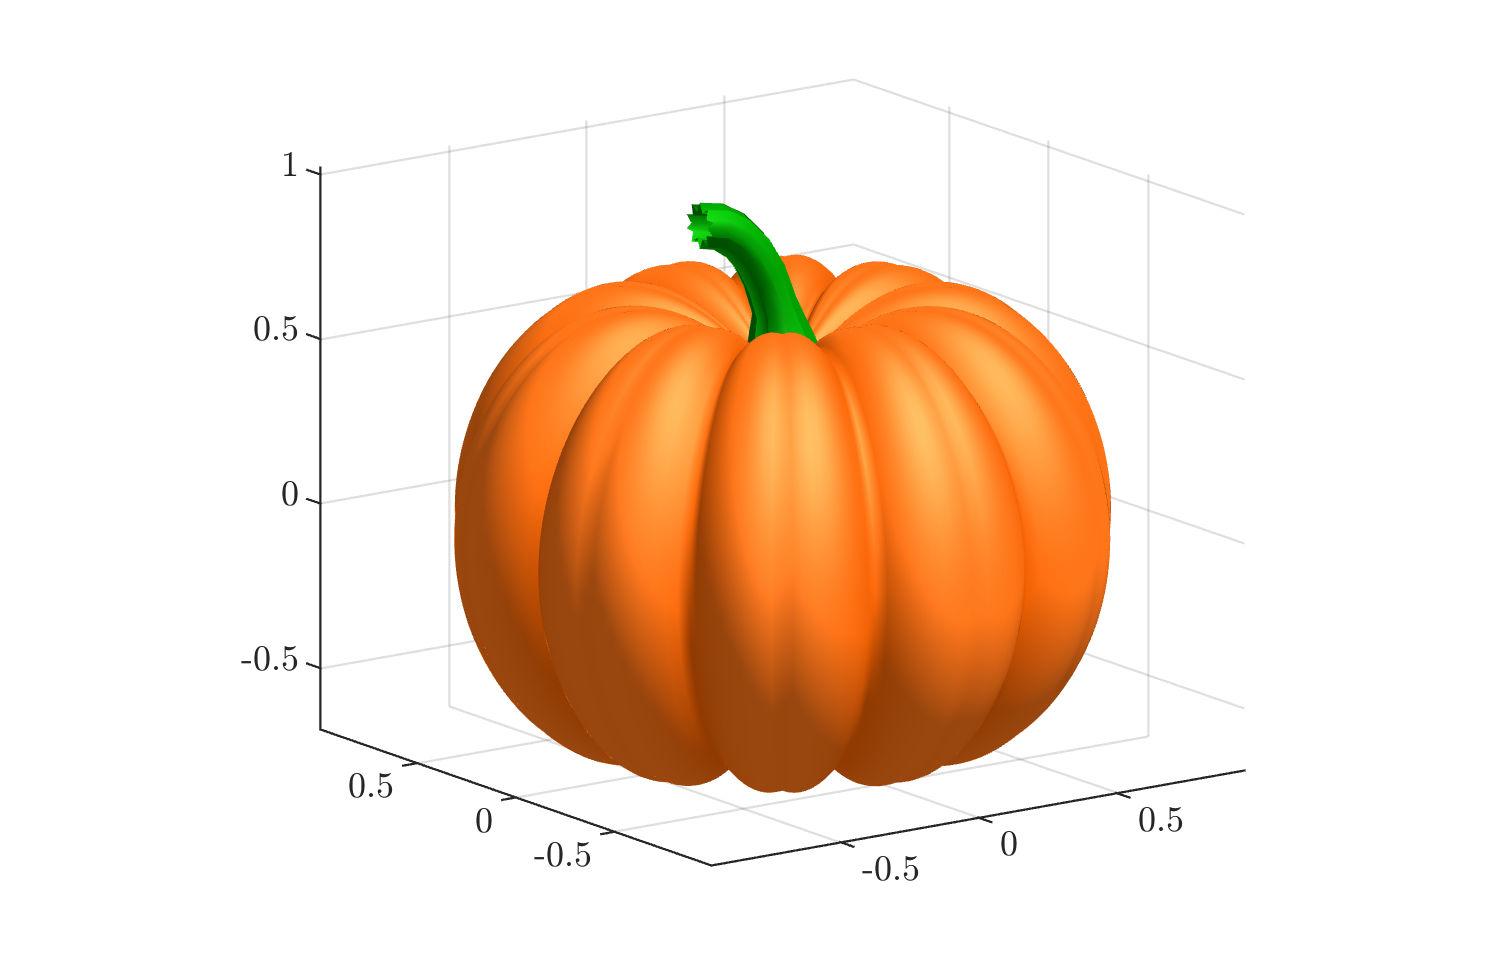

surf(Xp,Yp,Zp,Cp,'Clipping','off')
shading interp
colormap([ linspace(.94, 1, 256); linspace(.37, .46, 256); linspace(0, .1, 256) ]')
surface(Xs,Ys,Zs,[],'FaceColor', '#008000', 'EdgeColor','none', 'Clipping','off')
material([ .6, .9, .3, 2, .5 ])
lighting g
axis('equal')

camlight

view([-35.680 14.364])

## DRAW2

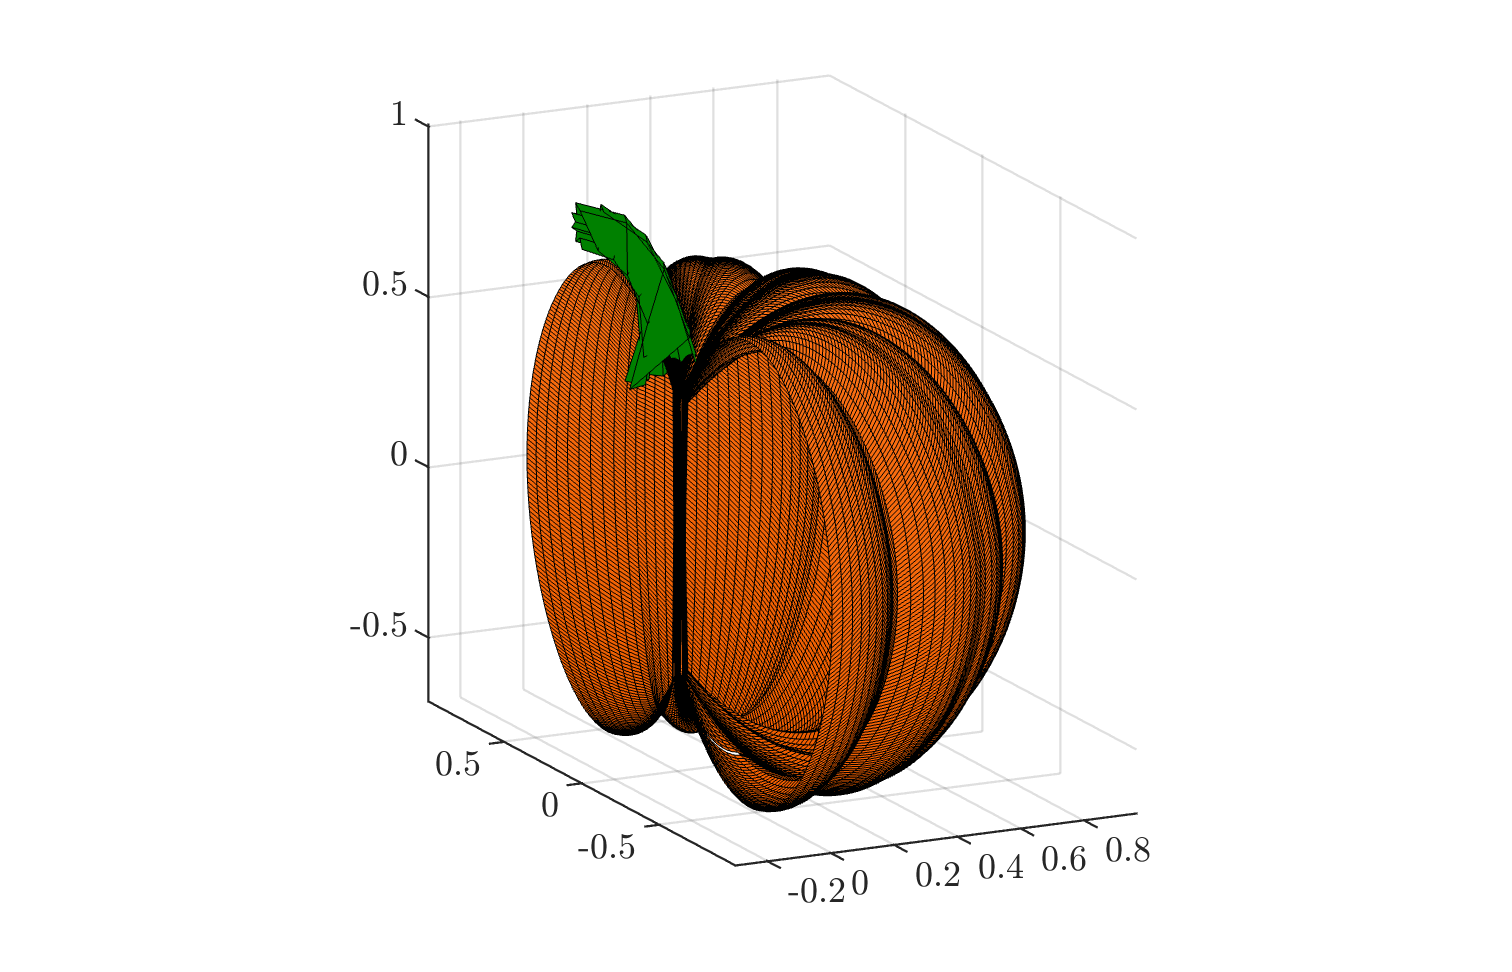

cla
xPn = reshape(Xp(Xp > 0),200,[]);
yPn = reshape(Yp(Xp > 0),200,[]);
zPn = reshape(Zp(Xp > 0),200,[]);

xSn = reshape(Xs(Ys > 0),20,[]);
ySn = reshape(Ys(Ys > 0),20,[]);
zSn = reshape(Zs(Ys > 0),20,[]);

surf(xPn,yPn,zPn)
hold on
surf(xSn,ySn,zSn,'FaceColor', '#008000')

axis('equal')

view([-35.680 14.364])